**ECE-524 Radio System Design**

**Author: Cristian Salitre**

**Date: 01-16-2025**

**Professor: Dr. Besnoff**

clc;
clear;

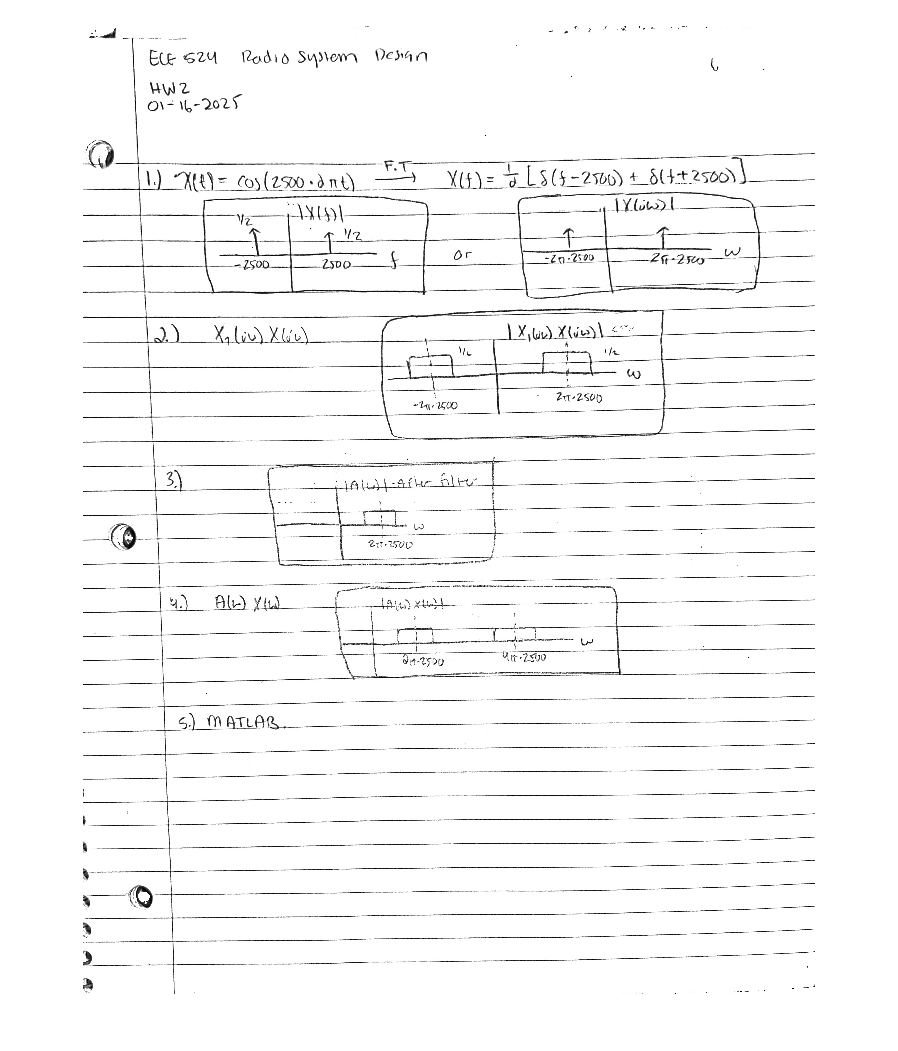

% Open handwritten part of HW2
HW1_img = imread('ECE_524_HW2.png');
figure('Units', 'normalized', 'OuterPosition', [0 0 1 1]);
imshow(HW1_img, 'InitialMagnification', 100);

**Problem 5:** Plot signals given

% Signal 1: x(t) = 0.8 * cos(100*2pi*t) * cos*(500 * 2pi)
% Signal 2: y(t) = cos(2500*2pi*t)
% AM: x(t)y(t)

%% NOTE: fft(abs(function)) wil provide the frequency spectrum

% Parameters
Fs = 1e4;
T = 1/Fs;
L = 1e2;
t = (0:L-1)*T;

% Signal 1
x = 0.8*cos(100*2*pi*t) .* cos(500*pi*t);

% Signal 2
y = cos(2500*2*pi*t) .* x;

% Compute FFTs
X = fft(x);
Y = fft(y);

% Process FFT results
X2 = abs(X/L);
Y2 = abs(Y/L);

% Take single-sided spectrum
X1 = X2(1:L/2+1);
Y1 = Y2(1:L/2+1);
f = Fs*(0:(L/2))/L;

**Part a**: plot x(t) and the modulated signal in the time domain

figure;

% Time domain plots
subplot(2,1,1);
plot(t, x, 'b', 'LineWidth', 1.5);
hold on;
plot(t, y, 'r', 'LineWidth', 1.5);
hold off;
title('Time Domain Signals');
xlabel('Time (s)');
ylabel('Amplitude');
legend('x(t) = 0.8cos(2\pi100t) cos(2\pi500t)', 'y(t) = x(t)cos(2\pi2500t)');
grid on;

**Part b: **plot x(t) and the modulated signal in the frequency domain

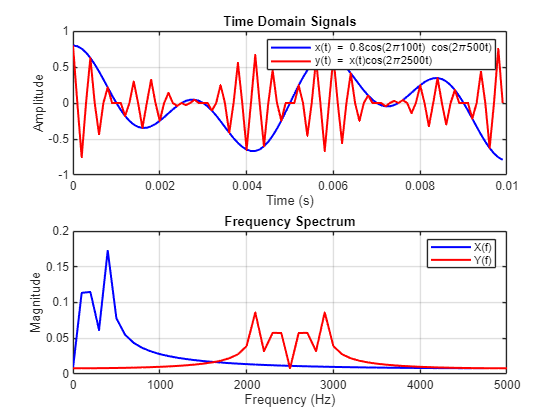


% Frequency domain plots
subplot(2,1,2);
plot(f, X1, 'b', 'LineWidth', 1.5);
hold on;
plot(f, Y1, 'r', 'LineWidth', 1.5);
hold off;
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('X(f)', 'Y(f)');
grid on;